# Widgets Toolbox - MATLAB App Building Components - Examples

*Copyright 2020 The MathWorks, Inc.*

## Button Grid

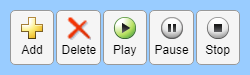

% Create a figure with a grid layout
figObj = uifigure("Position",[100 100 250 75]);
gridObj = uigridlayout(figObj,[1 1],"BackgroundColor",[.6 .8 1]);

% Create the widget
buttonGridWidget = wt.ButtonGrid(gridObj);

% Configure the widget
buttonGridWidget.BackgroundColor = [.6 .8 1];

% Add optional icons
buttonGridWidget.Icon = [
    "add_24.png"
    "delete_24.png"
    "play_24.png"
    "pause_24.png"
    "stop_24.png"
    ];

% Add optional text
buttonGridWidget.Text = [
    "Add"
    "Delete"
    "Play"
    "Pause"
    "Stop"
    ];

% Add optional tooltip
buttonGridWidget.Tooltip = [
    "Press to Add"
    "Press to Delete"
    "Press to Play"
    "Press to Pause"
    "Press to Stop"
    ];


% Assign a callback
buttonGridWidget.ButtonPushedFcn = @(h,e)disp(e)

buttonGridWidget =   ButtonGrid with properties:

               Icon: ["add_24.png"    "delete_24.png"    "play_24.png"    "pause_24.png"    "stop_24.png"]
               Text: ["Add"    "Delete"    "Play"    "Pause"    "Stop"]
            Tooltip: ["Press to Add"    "Press to Delete"    "Press to Play"    "Press to Pause"    "Press to Stop"]
          ButtonTag: [1×0 string]
       ButtonEnable: on
        Orientation: "horizontal"
      IconAlignment: "top"
        ButtonWidth: {'1x'  '1x'  '1x'  '1x'  '1x'}
       ButtonHeight: {'1x'}
    ButtonPushedFcn: @(h,e)disp(e)
           Position: [11 11 230 55]

  Show all properties


## Checkbox List

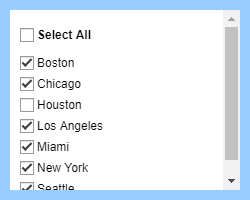

% Create a figure with a grid layout
figObj = uifigure("Position",[100 100 250 200]);
gridObj = uigridlayout(figObj,[1 1],"BackgroundColor",[.6 .8 1]);

% Create the widget
cbListWidget = wt.CheckboxList(gridObj);

% Configure the widget
cbListWidget.Items = [
    "Boston"
    "Chicago"
    "Houston"
    "Los Angeles"
    "Miami"
    "New York"
    "Seattle"
    ];
cbListWidget.Value(3) = false;

% This is optional (default is false)
cbListWidget.ShowSelectAll = true;


% Assign a callback
cbListWidget.ValueChangedFcn = @(h,e)disp(e)

cbListWidget =   CheckboxList with properties:

              Items: [7×1 string]
              Value: [7×1 logical]
      ShowSelectAll: 1
    ValueChangedFcn: @(h,e)disp(e)
           Position: [100 100 100 100]

  Show all properties


## Color Selector

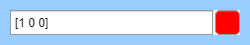

% Create a figure with a grid layout
figObj = uifigure("Position",[100 100 250 45]);
gridObj = uigridlayout(figObj,[1 1],"BackgroundColor",[.6 .8 1]);

% Create the widget
colorWidget = wt.ColorSelector(gridObj);

% Configure the widget
colorWidget.Value = [1 0 0];


% Assign a callback
colorWidget.ValueChangedFcn = @(h,e)disp(e)

colorWidget =   ColorSelector with properties:

              Value: [1 0 0]
      ShowEditField: 1
    ValueChangedFcn: @(h,e)disp(e)
           Position: [100 100 100 100]

  Show all properties


If you want to have only the button with no edit field:

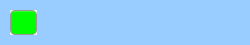

% Change the color
colorWidget.Value = [0 1 0];

% Turn off the edit field
colorWidget.ShowEditField = false;


% Make it a sensible width
gridObj.ColumnWidth = {27}

gridObj =   GridLayout with properties:

      RowHeight: {'1x'}
    ColumnWidth: {[27]}

  Show all properties


## File Selector

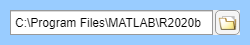

% Create a figure with a grid layout
figObj = uifigure("Position",[100 100 250 45]);
gridObj = uigridlayout(figObj,[1 1],"BackgroundColor",[.6 .8 1]);

% Create the widget
fileWidget = wt.FileSelector(gridObj);

% Configure the widget
fileWidget.Value = matlabroot;


% Assign a callback
fileWidget.ValueChangedFcn = @(h,e)disp(e)

fileWidget =   FileSelector with properties:

               Value: "C:\Program Files\MATLAB\R2020b"
            FullPath: "C:\Program Files\MATLAB\R2020b"
    ValueIsValidPath: 1
       SelectionType: "file"
       RootDirectory: ""
         ShowHistory: 0
             History: "C:\Program Files\MATLAB\R2020b"
    DefaultDirectory: ""
     ValueChangedFcn: @(h,e)disp(e)
            Position: [100 100 100 100]

  Show all properties


If you want to have a dropdown button to show recent history:

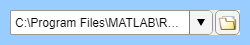

fileWidget.ShowHistory = true;

## List Selector (single pane)

The List Selector widget is intended for adding items to a list from a known set. You can optionally enable reordering the items, and add custom buttons.

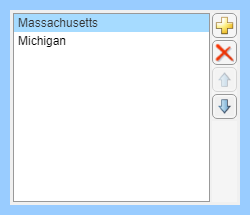

% Create a figure with a grid layout
figObj = uifigure("Position",[100 100 250 215]);
gridObj = uigridlayout(figObj,[1 1],"BackgroundColor",[.6 .8 1]);

% Create the widget
listWidget = wt.ListSelector(gridObj);
listWidget.Items = ["California","Massachusetts","Michigan","Texas"];
listWidget.Value = ["Massachusetts","Michigan"];


% Assign a callback
listWidget.ValueChangedFcn = @(h,e)disp(e)

listWidget =   ListSelector with properties:

                         Items: ["California"    "Massachusetts"    "Michigan"    "Texas"]
                     ItemsData: [1×0 double]
               AllowDuplicates: 0
                 SelectedIndex: [2 3]
                         Value: ["Massachusetts"    "Michigan"]
              HighlightedValue: "Massachusetts"
                   ButtonWidth: 25
                   UserButtons: [1×1 ButtonGrid]
                   ListButtons: [1×1 ButtonGrid]
               ButtonPushedFcn: ''
               ValueChangedFcn: @(h,e)disp(e)
    HighlightedValueChangedFcn: ''
                      Position: [100 100 100 100]

  Show all properties


You can also add your own custom buttons:

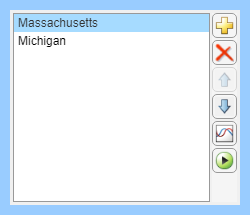

listWidget.UserButtons.Icon = ["plot_24.png","play_24.png"];

listWidget.UserButtons.ButtonHeight = {25 25};
listWidget.ButtonPushedFcn = @(h,e)disp(e);

## List Selector Two Pane

The List Selector Two-Pane widget is similar to the one-pane variant. It is intended for adding items to a list from a known set. In this case, the set of available items is displayed in a list on the left side, and items are selectively added to the right list.

Again you can optionally enable reordering the items and add custom buttons.

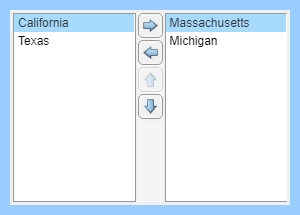

% Create a figure with a grid layout
figObj = uifigure("Position",[100 100 300 215]);
gridObj = uigridlayout(figObj,[1 1],"BackgroundColor",[.6 .8 1]);

% Create the widget
listWidget2 = wt.ListSelectorTwoPane(gridObj);
listWidget2.Items = ["California","Massachusetts","Michigan","Texas"];
listWidget2.Value = ["Massachusetts","Michigan"];

## Password Field

% Create a figure with a grid layout
figObj = uifigure("Position",[100 100 250 45]);
gridObj = uigridlayout(figObj,[1 2],"BackgroundColor",[.6 .8 1]);
gridObj.ColumnWidth = {'fit','1x'};

% Add label
uilabel(gridObj,"Text","Password:");

This component won't show in the preview, but it will create a password field with  text displayed as dots.

% Create the widget
passwordWidget = wt.PasswordField(gridObj);

% Configure the widget
passwordWidget.Value = "MathWorks";

## Progress Bar

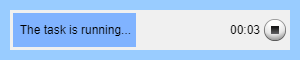

% Create a figure with a grid layout
figObj = uifigure("Position",[100 100 300 60]);
gridObj = uigridlayout(figObj,[1 1],"BackgroundColor",[.6 .8 1]);

% Create the widget
progressWidget = wt.ProgressBar(gridObj);

% Configure the widget
progressWidget.ShowCancel = true;


% Assign a callback
progressWidget.CancelPressedFcn = @(h,e)disp("Cancel Pressed!")

progressWidget =   ProgressBar with properties:

    ShowTimeRemaining: 1
           ShowCancel: 1
        Indeterminate: 0
             BarColor: [0.5000 0.7000 1]
                Value: 0
           StatusText: ""
              Running: 0
      CancelRequested: 0
            StartTime: NaT
          ElapsedTime: NaN
        RemainingTime: NaN
     CancelPressedFcn: @(h,e)disp("Cancel Pressed!")
             Position: [100 100 100 100]

  Show all properties



% Start the progress bar
progressWidget.startProgress("The task is starting...");

% Wait some time to simulate a running task
pause(2)

% Update the task progress
progressWidget.setProgress(0.5, "The task is running...");

Then, when the task is done:

% Wait some time to simulate a running task
pause(2)

% Mark the task finished
progressWidget.finishProgress("The task is finished");

If you want an indeteriminate progress bar:

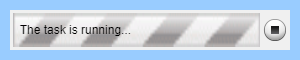

% Mark the task finished
progressWidget.Indeterminate = true;


% Start the progress bar
progressWidget.startProgress("The task is running...");

## Slider Checkbox Combination Group

% Create a figure with a grid layout
figObj = uifigure("Position",[100 100 250 125]);
gridObj = uigridlayout(figObj,[1 1],"BackgroundColor",[.6 .8 1]);

% Create the widget
sliderCheckboxWidget = wt.SliderCheckboxGroup(gridObj);

% Configure the widget
sliderCheckboxWidget.Name = ["Red", "Green", "Blue", "Alpha"];
sliderCheckboxWidget.CheckboxWidth = 100

sliderCheckboxWidget =   SliderCheckboxGroup with properties:

               Name: ["Red"    "Green"    "Blue"    "Alpha"]
              State: [1 1 1 1]
              Value: [1 1 1 1]
          RowHeight: 25
      CheckboxWidth: 100
    ValueChangedFcn: []
           Position: [100 100 100 100]

  Show all properties


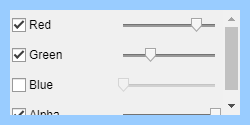

sliderCheckboxWidget.Value = [0.8, 0.3, 0, 1];
sliderCheckboxWidget.State = [true, true, false, true];


% Assign a callback
sliderCheckboxWidget.ValueChangedFcn = @(h,e)disp(e)

sliderCheckboxWidget =   SliderCheckboxGroup with properties:

               Name: ["Red"    "Green"    "Blue"    "Alpha"]
              State: [1 1 0 1]
              Value: [0.8000 0.3000 0 1]
          RowHeight: 25
      CheckboxWidth: 100
    ValueChangedFcn: @(h,e)disp(e)
           Position: [11 11 230 105]

  Show all properties


## Slider Spinner Combination

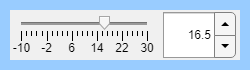

% Create a figure with a grid layout
figObj = uifigure("Position",[100 100 250 70]);
gridObj = uigridlayout(figObj,[1 1],"BackgroundColor",[.6 .8 1]);

% Create the widget
sliderSpinnerWidget = wt.SliderSpinner(gridObj);


% Configure the widget
sliderSpinnerWidget.Limits = [-10 30];
sliderSpinnerWidget.RoundFractionalValues = "off";
sliderSpinnerWidget.Step = 0.5;
sliderSpinnerWidget.Value = 16.5;

% Assign a callback
sliderSpinnerWidget.ValueChangedFcn = @(h,e)disp(e)

sliderSpinnerWidget =   SliderSpinner with properties:

                    Value: 16.5000
                   Limits: [-10 30]
                     Step: 0.5000
    RoundFractionalValues: off
       ValueDisplayFormat: '%11.4g'
              Orientation: 'horizontal'
              SpinnerSize: 75
          MajorTickLabels: [0 20 40 60 80 100]
      MajorTickLabelsMode: 'auto'
               MajorTicks: [0 20 40 60 80 100]
           MajorTicksMode: 'auto'
          MinorTickLabels: []
               MinorTicks: []
           MinorTicksMode: 'auto'
          ValueChangedFcn: @(h,e)disp(e)
         ValueChangingFcn: ''
                 Position: [100 100 100 100]

  Show <a href="matlab:if exist('sliderSpinnerWidget', 'var'), matlab.graphics.internal.getForDisplay('sliderSpinnerWidget', sliderSpinnerWidget, 'wt.SliderSpinner'), else, matlab.graphics.internal.getForDisplay('sliderSpinnerWidget'), end">all properties<

## Task Status Table

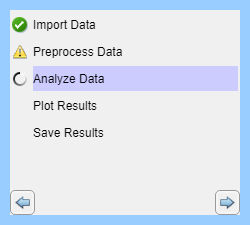

% Create a figure with a grid layout
figObj = uifigure("Position",[100 100 250 225]);
gridObj = uigridlayout(figObj,[1 1],"BackgroundColor",[.6 .8 1]);

% Create the widget
taskStatusWidget = wt.TaskStatusTable(gridObj);

% Configure the widget
taskStatusWidget.Items = [
    "Import Data"
    "Preprocess Data"
    "Analyze Data"
    "Plot Results"
    "Save Results"
    ];
taskStatusWidget.Status = [
    "complete"
    "warning"
    "running"
    "none"
    "none"
    ];
taskStatusWidget.SelectedIndex = 3;


% Assign a callback
taskStatusWidget.ButtonPushedFcn = @(h,e)disp(e)

taskStatusWidget =   TaskStatusTable with properties:

              Items: [5×1 string]
             Status: [5×1 string]
          RowHeight: 25
      SelectedIndex: 3
     SelectionColor: [0.8000 0.8000 1]
      ShowButtonRow: 1
      StatusMessage: ""
      EnableForward: 1
         EnableBack: 1
    ButtonPushedFcn: @(h,e)disp(e)
           Position: [100 100 100 100]

  Show all properties


## Toolbar

### Horizontal Sections

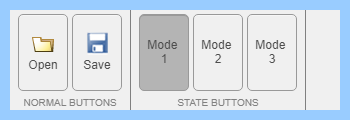

% Create a figure with a grid layout
figObj = uifigure("Position",[100 100 350 120]);
gridObj = uigridlayout(figObj,[1 1],"BackgroundColor",[.6 .8 1]);

% Create the widget
toolbarWidget1 = wt.Toolbar(gridObj);

% Create a horizontal section
section1 = wt.toolbar.HorizontalSection();
section1.Title = "NORMAL BUTTONS";
section1.addButton("open_24.png", "Open");
section1.addButton("save_24.png", "Save");

% Create a horizontal section with state buttons
section2 = wt.toolbar.HorizontalSection();
section2.Title = "STATE BUTTONS";
stateButton1 = section2.addStateButton("","Mode 1");
stateButton2 = section2.addStateButton("","Mode 2");
stateButton3 = section2.addStateButton("","Mode 3");

% Set the state of the buttons
stateButton1.Value = true;
stateButton2.Value = false;
stateButton3.Value = false;

% Attach the horizontal sections to the toolbar
toolbarWidget1.Section = [
    section1
    section2
    ];


% Assign a callback
toolbarWidget1.ButtonPushedFcn = @(h,e)disp(e)

toolbarWidget1 =   Toolbar with properties:

            Section: [2×1 HorizontalSection]
       DividerColor: [0.5000 0.5000 0.5000]
    ButtonPushedFcn: @(h,e)disp(e)
           Position: [11 11 330 100]

  Show all properties


## Toolbar

### Vertical sections

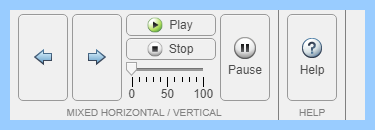

% Create a figure with a grid layout
figObj = uifigure("Position",[100 100 375 130]);
gridObj = uigridlayout(figObj,[1 1],"BackgroundColor",[.6 .8 1]);

% Create the widget
toolbarWidget2 = wt.Toolbar(gridObj);

% Create a horizontal section with vertical subsection
section3 = wt.toolbar.HorizontalSection();
section3.Title = "MIXED HORIZONTAL / VERTICAL";
section3.addButton("left_24.png","");
section3.addButton("right_24.png","");

% Create the vertical subsection
section3v1 = section3.addVerticalSection();
section3v1.addButton("play_24.png","Play");
section3v1.addButton("stop_24.png","Stop");

% Add a manual component to the  vertical section
sliderObj = uislider("Parent",[]);
section3v1.Component(end+1) = sliderObj;

% Attach a callback to the slider
% This is required for manually adding components
sliderObj.ValueChangedFcn = @(h,e)disp(e);

% Create more horizontal items
section3.addButton("pause_24.png","Pause");

% Add another basic section
section4 = wt.toolbar.HorizontalSection();
section4.Title = "HELP";
section4.addButton('help_24.png','Help');

% Attach the horizontal sections to the toolbar
toolbarWidget2.Section = [
    section3
    section4
    ];


% Assign a callback
toolbarWidget2.ButtonPushedFcn = @(h,e)disp(e)

toolbarWidget2 =   Toolbar with properties:

            Section: [2×1 HorizontalSection]
       DividerColor: [0.5000 0.5000 0.5000]
    ButtonPushedFcn: @(h,e)disp(e)
           Position: [11 11 355 110]

  Show all properties
